Starting parallel pool (parpool) using the 'Processes' profile ...
Preserving jobs with IDs: 11 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile Processes. To create 'myCluster' use 'myCluster = parcluster('Processes')'.
Connected to parallel pool with 4 workers.


generate_given_plot(0.35,2500,2506,"false",'C:\Users\pawel\Downloads\beta-divergence-based-recurrence-plots-for-audio-time-series-analysis-master\beta-divergence-based-recurrence-plots-for-audio-time-series-analysis-master\chb-mit-scalp-eeg-database-1.0.0\chb-mit-scalp-eeg-database-1.0.0\chb20\chb20_13.edf',"chb02","16",8);

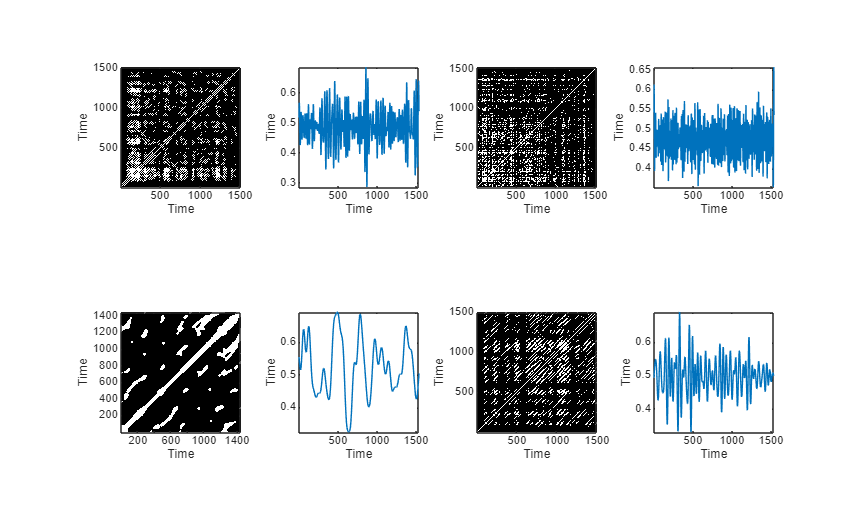

generate_given_plot(0.35,100,106,"false",'C:\Users\pawel\Downloads\beta-divergence-based-recurrence-plots-for-audio-time-series-analysis-master\beta-divergence-based-recurrence-plots-for-audio-time-series-analysis-master\chb-mit-scalp-eeg-database-1.0.0\chb-mit-scalp-eeg-database-1.0.0\chb20\chb20_13.edf',"chb02","16",8);

function pl = generate_given_plot(beta_par,start_t,end_t,isSeizure,route,patient,recording,number_of_channels)
    [data, header] = edfread(route);
    time_frame = [start_t,end_t];

    all_data = detrend(cell2mat(table2cell(data)));
    all_data = all_data((time_frame(1) * 256) + 1 : time_frame(2) * 256, :);
    [alpha,beta,delta,theta] = normalize_data(all_data(:,1:number_of_channels),number_of_channels);
    pl = 0;



    [rm_alpha,rm_beta,rm_delta,rm_theta] = compute_recurrences(alpha,beta,delta,theta,beta_par,number_of_channels);

    [tm_alpha,tm_beta,tm_delta,tm_theta] = compute_tresholds(rm_alpha,rm_beta,rm_delta,rm_theta);

    combined_alpha = mean(alpha, 2); % Average across the 23 channels
    combined_beta = mean(beta, 2); % Average across the 23 channels
    combined_delta = mean(delta, 2); % Average across the 23 channels
    combined_theta = mean(theta, 2); % Average across the 23 channels

    plots_part(tm_alpha,tm_beta,tm_delta,tm_theta,combined_alpha,combined_beta,combined_delta,combined_theta,beta_par,start_t,end_t,isSeizure,patient,recording);
end

function [alpha, beta, delta, theta] = normalize_data(all_data,number_of_channels)
    for i = 1:number_of_channels
        all_data(:,i) = hampel(all_data(:,i));
    end
    fs = 256;
    
    % Apply bandpass filters to each frequency range
    delta  = bandpass(all_data, [0.5 4], fs);   % Delta: 0.5–4 Hz
    theta  = bandpass(all_data, [4 8], fs);     % Theta: 4–8 Hz
    alpha  = bandpass(all_data, [8 13], fs);    % Alpha: 8–12 Hz
    beta   = bandpass(all_data, [13 30], fs);   % Beta: 12–30 Hz
    
    % Normalize each channel separately
    
    
    % Apply normalization to each channel in each frequency band
    delta = normalize(delta,1,"range", [0.0001,1]);
    theta = normalize(theta,1,"range", [0.0001,1]);
    alpha = normalize(alpha,1,"range", [0.0001,1]);
    beta  = normalize(beta,1,"range", [0.0001,1]);
end


function td = compute_time_delay(series)
    [taus, ami_values] = AMI(series, 30, 10);
    [~, local_minima] = findpeaks(-ami_values);  % Invert AMI to find minima

    if ~isempty(local_minima)
        td = taus(local_minima(1));  % First local minimum
    else
        [~, min_index] = min(ami_values);
        td = taus(min_index);  % Fallback: Global minimum
    end
 
end

function [m_opt, fnn_ratio] = compute_fnn(time_series, max_m, tau, threshold)
    % Compute False Nearest Neighbors (FNN) to determine optimal embedding dimension (m).
    %
    % Parameters:
    % - time_series: 1D array of time series data
    % - max_m: Maximum embedding dimension to test
    % - tau: Time delay (from AMI)
    % - threshold: Distance threshold for FNN
    %
    % Returns:
    % - m_opt: Optimal embedding dimension
    % - fnn_ratio: Percentage of false nearest neighbors for each m

    N = length(time_series);
    fnn_ratio = zeros(1, max_m);
    
    for m = 1:max_m
        % Create embedded vectors
        M = N - (m - 1) * tau;
        X = zeros(M, m);
        for i = 1:m
            X(:, i) = time_series((1:M) + (i - 1) * tau);
        end
        
        % Compute distances between nearest neighbors
        dist = squareform(pdist(X));  % Pairwise distances
        [~, nearest_idx] = sort(dist, 2);
        
        % Find false nearest neighbors
        false_neighbors = 0;
        for i = 1:M
            idx = nearest_idx(i, 2);  % Nearest neighbor (excluding itself)
            d_m = dist(i, idx);       % Distance in m-dim space
            d_m1 = abs(time_series(i + m * tau) - time_series(idx + m * tau)); % Distance in m+1

            if d_m > 0 && (d_m1 / d_m) > threshold
                false_neighbors = false_neighbors + 1;
            end
        end
        
        % Compute FNN percentage
        fnn_ratio(m) = (false_neighbors / M) * 100;
        
        % Stop if FNN drops below 1%
        if fnn_ratio(m) < 1
            m_opt = m;
            return;
        end
    end
    
    % If no minimum found, take the lowest FNN value
    [~, m_opt] = min(fnn_ratio);
end


function [rm_alpha,rm_beta,rm_delta,rm_theta] = compute_recurrences(wanted_alpha,wanted_beta,wanted_delta,wanted_theta,beta_div,number_of_channels)
    
    % Number of columns (channels)
    td_alpha = compute_time_delay(wanted_alpha(:,:,1));
    td_beta = compute_time_delay(wanted_beta(:,:,1));
    td_delta = compute_time_delay(wanted_delta(:,:,1));
    td_theta = compute_time_delay(wanted_theta(:,:,1));

    m_alpha = compute_fnn(wanted_alpha,20,td_alpha,15);
    m_beta = compute_fnn(wanted_beta,20,td_beta,15);
    m_delta = compute_fnn(wanted_delta,20,td_delta,15);
    m_theta = compute_fnn(wanted_theta,20,td_theta,15);



    % Run once to get the size of an RM (assuming fixed size)
    sample_rm_alpha = computeRM_blockedkronecker_nonsymmetric(wanted_alpha(:, 1), m_alpha, td_alpha, 40, beta_div);
    sample_rm_beta = computeRM_blockedkronecker_nonsymmetric(wanted_beta(:, 1), m_beta, td_beta, 40, beta_div);
    sample_rm_delta = computeRM_blockedkronecker_nonsymmetric(wanted_delta(:, 1), m_delta, td_delta, 40, beta_div);
    sample_rm_theta = computeRM_blockedkronecker_nonsymmetric(wanted_theta(:, 1), m_theta, td_theta, 40, beta_div);

    % Preallocate a logical 3D array (fastest)
    [N_alpha, M_alpha] = size(sample_rm_alpha);  % Get matrix size
    [N_beta, M_beta] = size(sample_rm_beta);  % Get matrix size
    [N_delta, M_delta] = size(sample_rm_delta);  % Get matrix size
    [N_theta, M_theta] = size(sample_rm_theta);  % Get matrix size

    
    % Compute recurrence matrices in a loop
    rm_alpha = zeros(N_alpha, M_alpha); % Initialize for averaging
    rm_beta = zeros(N_beta, M_beta);
    rm_delta = zeros(N_delta, M_delta);
    rm_theta = zeros(N_theta, M_theta);

    parfor i = 1:number_of_channels
        rm_alpha = rm_alpha + computeRM_blockedkronecker_nonsymmetric(wanted_alpha(:, i), m_alpha, td_alpha, 40, beta_div);
        rm_beta = rm_beta + computeRM_blockedkronecker_nonsymmetric(wanted_beta(:, i), m_beta, td_beta, 40, beta_div);
        rm_delta = rm_delta + computeRM_blockedkronecker_nonsymmetric(wanted_delta(:, i), m_delta, td_delta, 40, beta_div);
        rm_theta = rm_theta + computeRM_blockedkronecker_nonsymmetric(wanted_theta(:, i), m_theta, td_theta, 40, beta_div);
    end

    % Compute the mean across all channels
    rm_alpha = rm_alpha / number_of_channels;
    rm_beta = rm_beta / number_of_channels;
    rm_delta = rm_delta / number_of_channels;
    rm_theta = rm_theta / number_of_channels;

end

  

function [tm_alpha, tm_beta, tm_delta, tm_theta] = compute_tresholds(rm_alpha, rm_beta, rm_delta, rm_theta)
    % COMPUTE_THRESHOLDS - Compute binary recurrence matrices by applying optimal thresholds.
    %   [tm_alpha, tm_beta, tm_delta, tm_theta] = compute_thresholds(rm_alpha, rm_beta, rm_delta, rm_theta)
    %   thresholds recurrence matrices for alpha, beta, delta, and theta bands using entropy maximization.
    %
    % Inputs:
    %   rm_alpha, rm_beta, rm_delta, rm_theta - Recurrence matrices (2D, averaged across channels)
    % Outputs:
    %   tm_alpha, tm_beta, tm_delta, tm_theta - Binary thresholded matrices (2D)

    % Define the percentile range to search (configurable if needed)
    percentile_range = 5:15; % Explore percentiles from 1% to 20%
    
    % Compute optimal thresholds using entropy maximization
    threshold_alpha = find_optimal_threshold(rm_alpha, percentile_range);
    threshold_beta  = find_optimal_threshold(rm_beta, percentile_range);
    threshold_delta = find_optimal_threshold(rm_delta, percentile_range);
    threshold_theta = find_optimal_threshold(rm_theta, percentile_range);
    
    % Apply thresholding to create binary recurrence matrices
    tm_alpha = rm_alpha < threshold_alpha;
    tm_beta  = rm_beta < threshold_beta;
    tm_delta = rm_delta < threshold_delta;
    tm_theta = rm_theta < threshold_theta;
end

function optimal_threshold = find_optimal_threshold(rm, percentile_range, num_bins)
    % FIND_OPTIMAL_THRESHOLD - Find the threshold that maximizes Shannon entropy of the binary matrix.
    %   optimal_threshold = find_optimal_threshold(rm, percentile_range, num_bins)
    %
    % Inputs:
    %   rm              - Recurrence matrix (2D)
    %   percentile_range - Range of percentiles to test (e.g., 1:20)
    %   num_bins        - Number of bins for histogram (optional, default: 10)
    % Outputs:
    %   optimal_threshold - Threshold value maximizing entropy
    
    % Default number of bins if not provided
    if nargin < 3
        num_bins = 10;
    end
    
    % Input validation
    if isempty(rm) || ~ismatrix(rm)
        error('Recurrence matrix must be a non-empty 2D array.');
    end
    if isempty(percentile_range) || ~isvector(percentile_range)
        error('Percentile range must be a non-empty vector.');
    end
    
    % Precompute recurrence matrix values for efficiency
    rm_flat = rm(:);
    thresholds = prctile(rm_flat, percentile_range); % Compute all thresholds at once
    
    max_entropy = -inf;
    optimal_threshold = thresholds(round(end/2)); % Default to median percentile if no better found
    
    % Test each threshold
    for i = 1:length(thresholds)
        tm_test = rm_flat < thresholds(i); % Binary vector
        
        % Compute Shannon entropy
        prob_dist = histcounts(tm_test, num_bins, 'Normalization', 'probability');
        % Filter out zero probabilities to avoid log2(0); eps ensures numerical stability
        prob_dist = prob_dist(prob_dist > 0);
        if isempty(prob_dist)
            entropy_val = 0; % Handle edge case where all values are identical
        else
            entropy_val = -sum(prob_dist .* log2(prob_dist + eps));
        end
        
        % Update optimal threshold if entropy increases
        if entropy_val > max_entropy
            max_entropy = entropy_val;
            optimal_threshold = thresholds(i);
        end
    end
end


function f = plots_part(tm_alpha,tm_beta,tm_delta,tm_theta,combined_alpha,combined_beta,combined_delta,combined_theta,beta,start_time,end_time,isSeizure,patient,file)
    f = figure('Position', [100, 42, 1000, 600]);
    colormap([0 0 0 ; 1 1 1]);

    subplot(2,4,1);
    imagesc(tm_alpha);
    xlabel('Time');
    ylabel('Time');
    axis xy
    axis tight
    axis square

    subplot(2,4,2);
    plot(combined_alpha);
    xlabel('Time');
    ylabel('Time');
    axis xy
    axis tight
    axis square

    subplot(2,4,3);
    imagesc(tm_beta);
    xlabel('Time');
    ylabel('Time');
    axis xy
    axis tight
    axis square

    subplot(2,4,4);
    plot(combined_beta);
    xlabel('Time');
    ylabel('Time');
    axis xy
    axis tight
    axis square

    subplot(2,4,5);
    imagesc(tm_delta);
    xlabel('Time');
    ylabel('Time');
    axis xy
    axis tight
    axis square

    subplot(2,4,6);
    plot(combined_delta);
    xlabel('Time');
    ylabel('Time');
    axis xy
    axis tight
    axis square

    subplot(2,4,7);
    imagesc(tm_theta);
    xlabel('Time');
    ylabel('Time');
    axis xy
    axis tight
    axis square

    subplot(2,4,8);
    plot(combined_theta);
    xlabel('Time');
    ylabel('Time');
    axis xy
    axis tight
    axis square
% Define the correct file name
    name = fullfile("C:\Users\pawel\Downloads\beta-divergence-based-recurrence-plots-for-audio-time-series-analysis-master\\beta-divergence-based-recurrence-plots-for-audio-time-series-analysis-master\plots", ...
                patient + "_" + file + "_" + start_time + "_" + end_time + "_" + beta + "_" + isSeizure + ".fig");

% Save the figure correctly
    savefig(f, name);

end